Importing Covid'19 from JHU CSSEIG.

confirmed = loadData('confirmed');
deaths = loadData('deaths');
recovered = loadData('recovered');

region = 12; % Queensland
t = 12:width(confirmed);
t-11

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


qlpop = 5072000; 
s1 = qlpop - confirmed{region,t} - deaths{region,t} - recovered{region,t};
i1 = confirmed{region,t} - deaths{region,t} - recovered{region,t};
r1 = deaths{region,t} + recovered{region,t};

i0 = confirmed{region,t}

i0 =      1     3     2     3     2     2     3     3     4     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     9     9     9    11    11    13    13    13    15    15    18    20    20    35    46    61    68    78    94



t = 1:length(s1)-1;
M = transpose([s1; i1; r1;]);
M = [transpose(t) M(1:end-1,:) M(2:end,1)-M(1:end-1,1) M(2:end,3)-M(1:end-1,3)]

M =            1     5071999           1           0          -2           0
           2     5071997           3           0           1           0
           3     5071998           2           0          -1           0
           4     5071997           3           0           1           0
           5     5071998           2           0           0           0
           6     5071998           2           0          -1           0
           7     5071997           3           0           0           0
           8     5071997           3           0          -1           0
           9     5071996           4           0          -1           0
          10     5071995           5           0           0           0


dS = [M(:,1:3), M(:,5)]

dS =            1     5071999           1          -2
           2     5071997           3           1
           3     5071998           2          -1
           4     5071997           3           1
           5     5071998           2           0
           6     5071998           2          -1
           7     5071997           3           0
           8     5071997           3          -1
           9     5071996           4          -1
          10     5071995           5           0


dS = dS(dS(:,4)<0,:)

dS =            1     5071999           1          -2
           3     5071998           2          -1
           6     5071998           2          -1
           8     5071997           3          -1
           9     5071996           4          -1
          23     5071995           5          -1
          31     5071994           4          -4
          34     5071990           8          -2
          36     5071988          10          -9
          39     5071979           5          -2


dS(:,2).*dS(:,3)/qlpop

ans =     1.0000
    2.0000
    2.0000
    3.0000
    4.0000
    5.0000
    4.0000
    8.0000
   10.0000
    5.0000



fun=@(x,xdata)x(1)*1*exp(x(2)*xdata)./(x(1)+1*(exp(x(2)*xdata)-1))

fun = function_handle with value:
    @(x,xdata)x(1)*1*exp(x(2)*xdata)./(x(1)+1*(exp(x(2)*xdata)-1))


times = linspace(M(1, 1),M(end, 1));
lss = lsqcurvefit(fun,[1, .001], 1:length(i0), i0)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


lss = 	1.0e+03 *

    1.0714    0.0001


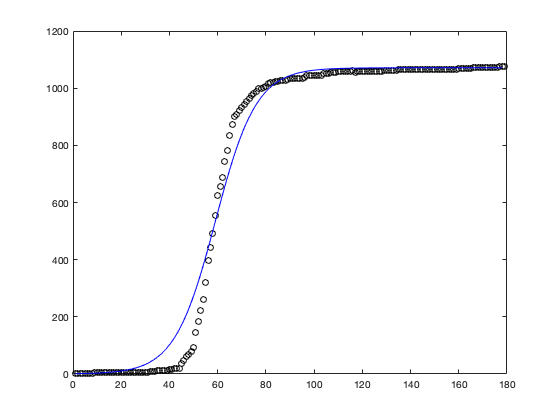


plot(1:length(i0), i0, 'ko',times, fun(lss,times),'b-')

differentiate(fun,1:length(i0))

Check for missing argument or incorrect argument data type in call to function 'differentiate'.

plot(abs(dS(:,4)))

% lsfun=@(x, xdata)-x(1).*xdata(1).*xdata(2)./qlpop
% lsfun=@(x,xdata)(x(1)*xdata(1)/qlpop*xdata(2))-x(2)*xdata(2);
% lss = lsqcurvefit(fun,(.35), dS(:,2:3), dS(:,4))

size(dS(:, 4))

ans =    107     1


size(dS(:,2:3))

ans =    107     2


lsfun=@(x, xdata)(-x(1).* xdata(:, 1).* xdata(:, 2)./qlpop);
lsfun([.387, .141], [dS(:,2) dS(:,3)])

ans =    -0.3870
   -0.7740
   -0.7740
   -1.1610
   -1.5480
   -1.9350
   -1.5480
   -3.0960
   -3.8700
   -1.9350


lss = lsqcurvefit(lsfun,[.387, .141], [dS(:,2) dS(:,3)], abs(dS(:, 4)))


Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


lss =    -0.0871    0.1410


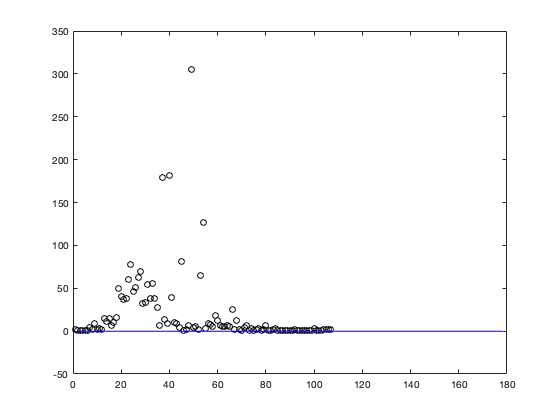


plot(1:length(dS), abs(dS(:, 4)), 'ko', times, fun(lss,times),'b-')

lsfun=@(x, xdata)(-x(1).* xdata(:, 1).* xdata(:, 2)./qlpop);
[t, s] = ode45(@(t, y), 0:length(i0)-1, 0)

Index in position 2 exceeds array bounds (must not exceed 1).

Error in LSS (line 35)
lsfun=@(x, xdata)(-x(1).* xdata(:, 1).* xdata(:, 2)./qlpop);

Error in odearguments (line 90)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{1} to yp0.

Error in 



function dCdt = odeFun(~,C,par)
%ODEFUN SIR model

    % unpack parameters
    beta  = par(1);
    gamma = par(2);
    N     = par(3);
    I0    = par(4);
    
    % set temp. vars
    c0    = I0/N;
    c     = C/N;

    % setup equation
    %dCdt = N*(1 - c)*(beta*c + gamma*log((1 - c)/(1 - c0)));
      dCdt = gamma*N*(1 - c - (1 - c0)*exp(-beta*c/gamma));
end